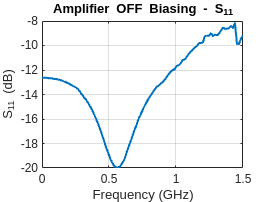

% -------------------------
% OFF BIASING
% -------------------------
S_off = sparameters('lab6_amplifier_OFF_biasing.s2p');
freq_off = S_off.Frequencies;

% Extract S11 and S21
S11_off = squeeze(S_off.Parameters(1,1,:));
S21_off = squeeze(S_off.Parameters(2,1,:));

% Convert to dB
S11_off_dB = 20*log10(abs(S11_off));
S21_off_dB = 20*log10(abs(S21_off));

% Plot S11 in its own figure
figure('Name','OFF Biasing - S11');
plot(freq_off/1e9, S11_off_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{11} (dB)');
title('Amplifier OFF Biasing - S_{11}');

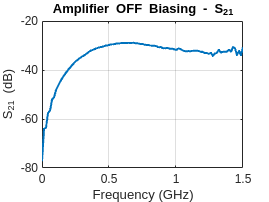


% Plot S21 in its own figure
figure('Name','OFF Biasing - S21');
plot(freq_off/1e9, S21_off_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{21} (dB)');
title('Amplifier OFF Biasing - S_{21}');

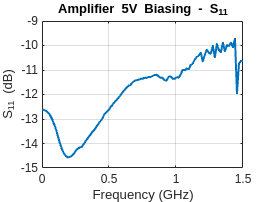



% -------------------------
% 5V BIASING
% -------------------------
S_5V = sparameters('lab6_amplifier_5V_biasing.s2p');
freq_5V = S_5V.Frequencies;

S11_5V = squeeze(S_5V.Parameters(1,1,:));
S21_5V = squeeze(S_5V.Parameters(2,1,:));

S11_5V_dB = 20*log10(abs(S11_5V));
S21_5V_dB = 20*log10(abs(S21_5V));

% Plot S11 in its own figure
figure('Name','5 V Biasing - S11');
plot(freq_5V/1e9, S11_5V_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{11} (dB)');
title('Amplifier 5V Biasing - S_{11}');

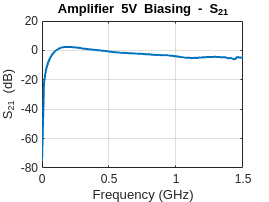


% Plot S21 in its own figure
figure('Name','5 V Biasing - S21');
plot(freq_5V/1e9, S21_5V_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{21} (dB)');
title('Amplifier 5V Biasing - S_{21}');

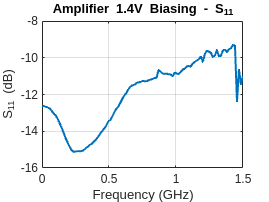



% -------------------------
% 1.4V BIASING
% -------------------------
S_1V4 = sparameters('lab6_amplifier_1.4V_biasing.s2p');
freq_1V4 = S_1V4.Frequencies;

S11_1V4 = squeeze(S_1V4.Parameters(1,1,:));
S21_1V4 = squeeze(S_1V4.Parameters(2,1,:));

S11_1V4_dB = 20*log10(abs(S11_1V4));
S21_1V4_dB = 20*log10(abs(S21_1V4));

% Plot S11 in its own figure
figure('Name','1.4 V Biasing - S11');
plot(freq_1V4/1e9, S11_1V4_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{11} (dB)');
title('Amplifier 1.4V Biasing - S_{11}');

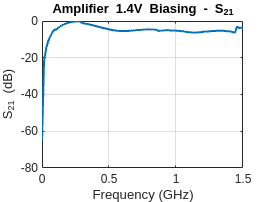


% Plot S21 in its own figure
figure('Name','1.4 V Biasing - S21');
plot(freq_1V4/1e9, S21_1V4_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{21} (dB)');
title('Amplifier 1.4V Biasing - S_{21}');

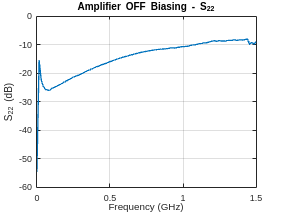

% ========================================================
% OFF BIASING - SWAPPED S22, S12
% ========================================================
S_off_SWAP = sparameters('lab6_amplifier_OFF_SWAP_biasing.s2p');
freq_off_SWAP = S_off_SWAP.Frequencies;

% Even though these are physically S22 and S12,
% we are reading them as "S11" and "S21" for convenience.
S11_off_SWAP = squeeze(S_off_SWAP.Parameters(1,1,:)); % This is actually S22 in your measurement
S21_off_SWAP = squeeze(S_off_SWAP.Parameters(2,1,:)); % This is actually S12 in your measurement

% Convert to dB
S11_off_SWAP_dB = 20*log10(abs(S11_off_SWAP));
S21_off_SWAP_dB = 20*log10(abs(S21_off_SWAP));

% Plot S22 (labeled) in its own figure
figure('Name','OFF Biasing - S22');
plot(freq_off_SWAP/1e9, S11_off_SWAP_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{22} (dB)');
title('Amplifier OFF Biasing - S_{22}');

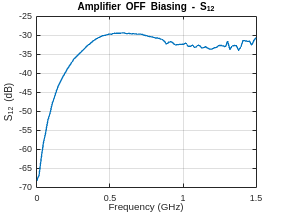


% Plot S12 (labeled) in its own figure
figure('Name','OFF Biasing - S12');
plot(freq_off_SWAP/1e9, S21_off_SWAP_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{12} (dB)');
title('Amplifier OFF Biasing - S_{12}');

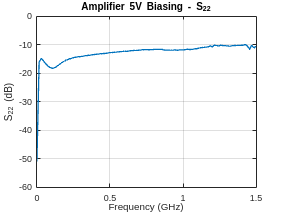



% ========================================================
% 5V BIASING - SWAPPED S22, S12
% ========================================================
S_5V_SWAP = sparameters('lab6_amplifier_5V_SWAP_biasing.s2p');
freq_5V_SWAP = S_5V_SWAP.Frequencies;

% Again, we label them S11, S21 in code, but these are physically S22, S12
S11_5V_SWAP = squeeze(S_5V_SWAP.Parameters(1,1,:)); 
S21_5V_SWAP = squeeze(S_5V_SWAP.Parameters(2,1,:));

S11_5V_SWAP_dB = 20*log10(abs(S11_5V_SWAP));
S21_5V_SWAP_dB = 20*log10(abs(S21_5V_SWAP));

% Plot S22
figure('Name','5 V Biasing - S22');
plot(freq_5V_SWAP/1e9, S11_5V_SWAP_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{22} (dB)');
title('Amplifier 5V Biasing - S_{22}');

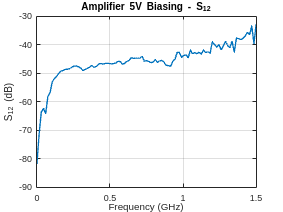


% Plot S12
figure('Name','5 V Biasing - S12');
plot(freq_5V_SWAP/1e9, S21_5V_SWAP_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{12} (dB)');
title('Amplifier 5V Biasing - S_{12}');

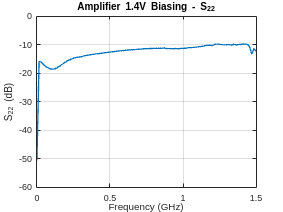



% ========================================================
% 1.4V BIASING - SWAPPED S22, S12
% ========================================================
S_1V4_SWAP = sparameters('lab6_amplifier_1.4V_SWAP_biasing.s2p');
freq_1V4_SWAP = S_1V4_SWAP.Frequencies;

S11_1V4_SWAP = squeeze(S_1V4_SWAP.Parameters(1,1,:)); 
S21_1V4_SWAP = squeeze(S_1V4_SWAP.Parameters(2,1,:));

S11_1V4_SWAP_dB = 20*log10(abs(S11_1V4_SWAP));
S21_1V4_SWAP_dB = 20*log10(abs(S21_1V4_SWAP));

% Plot S22
figure('Name','1.4 V Biasing - S22');
plot(freq_1V4_SWAP/1e9, S11_1V4_SWAP_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{22} (dB)');
title('Amplifier 1.4V Biasing - S_{22}');

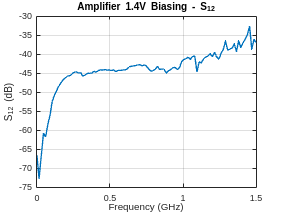


% Plot S12
figure('Name','1.4 V Biasing - S12');
plot(freq_1V4_SWAP/1e9, S21_1V4_SWAP_dB, 'LineWidth',1.5);
grid on;
xlabel('Frequency (GHz)');
ylabel('S_{12} (dB)');
title('Amplifier 1.4V Biasing - S_{12}');